%bundrof analysis for oversteer and understeer analysis
%made by PREETHAM A -team nitrox
clear;
format short;
theta_inner=0:50;%has to be assumed
theta_outer=0:50;
track_width=1371.6;
wheel_base=1550;
pivoted_dist=1047;
%perfect ackerman
%theta_outer=acotd((track_width/wheel_base)+cotd(theta_inner));

turning radius calculation

inner_turning_r=(wheel_base./tand(theta_inner))-((track_width-pivoted_dist)/2);
outer_turning_r=(wheel_base./tand(theta_outer))-((track_width-pivoted_dist)/2);

optimization

we have ;to ensure that inner turning radius is between 1200 to 2500 so the outer truning radius should be that + track width which is around 2500 to 3800.

temp1=inner_turning_r>1200 & inner_turning_r<2500;
temp2=outer_turning_r>2500 & outer_turning_r<3800;
inner_turning_r=inner_turning_r(temp1).*ones(nnz(temp2),1);
outer_turning_r=outer_turning_r(temp2)'.*ones(1,nnz(temp1));
theta_inner=theta_inner(temp1);
theta_outer=theta_outer(temp2);

now after applying these we have to minimize the turning radii.and maximmise the ackerman percentage.

for graphic visualization we can make two surfaces one for ackerman percentage and one for turning radius

ackerman_value=atand(wheel_base./((wheel_base./tand(theta_outer))-track_width));
ackerman_percentage=theta_inner./ackerman_value'*100;
% hold on;
% surf(theta_inner,theta_outer,ackerman_percentage)
% surf(theta_inner,theta_outer,inner_turning_r)
% surf(theta_inner,theta_outer,outer_turning_r)
% hold off;
ackerman_percentage=normalize2d(ackerman_percentage);
%as ackerman percentage is supposed to be max we will invert it so that max
%becomes min
ackerman_percentage=(ackerman_percentage-1)*-1;
inner_turning_r=normalize2d(inner_turning_r);
outer_turning_r=normalize2d(outer_turning_r);

now we have all values in range of 1 and 0 so we have to assign weighing ratios based on their importance so that they will plot out a graph based on requirements. **and the minima of the graph will be our result**

assuming importance ackerman percentage>outer min turning>inner min turning

6>4>3.

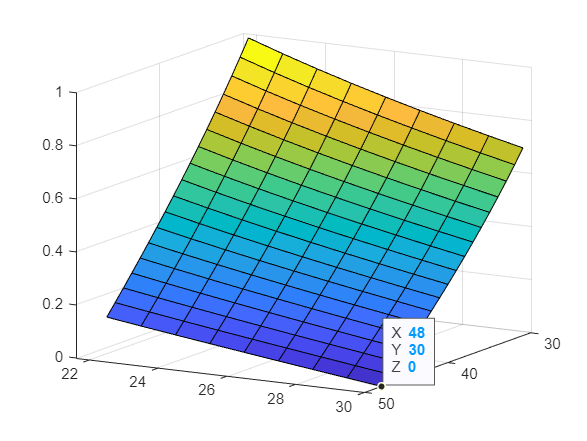

score=5*ackerman_percentage+4*outer_turning_r+3*inner_turning_r;
score=normalize2d(score);
surf(theta_inner,theta_outer,score)

ackerman_value=atand(wheel_base./((wheel_base./tand(30))-track_width));
ackerman_percentage=48./ackerman_value'*100

ackerman_percentage = 96.5203

function x = normalize2d (array)
    array=array-min(min(array));
    x=array/max(max(array));
end